clear; clc; close all;

split_percent = 0.7;
split_idx = length(labels) * split_percent;
X_Train = features(:, :, :, 1:split_idx);
Y_Train = labels(1:split_idx);
X_Test = features(:, :, :, split_idx+1:end);
Y_Test = labels(split_idx+1:end);

Y_Train = categorical(Y_Train);
Y_Test = categorical(Y_Test);

#### Sigmoid (optional)

Applying sigmoid can be used as a normalization

X_Train = dlarray(X_Train);
X_Test = dlarray(X_Test);
X_Train = 2 * sigmoid(X_Train) - 1;
X_Test = 2 * sigmoid(X_Test) - 1;
X_Train = extractdata(X_Train);
X_Test = extractdata(X_Test);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [4×4×2×420000 double]
      Labels: [2    4    6    6    4    5    4    2    3    3    5    6    3    3    5    3    1    3    1    1    5    1    1    1    2    3    3    3    6    6    2    6    6    2    5    4    6    3    3    4    6    5    1    2    2    6    …    ]


dsTest =   MyDataStore with properties:

    Features: [4×4×2×180000 double]
      Labels: [5    5    6    3    1    6    5    1    1    5    3    5    6    4    6    5    1    4    4    3    1    6    6    2    5    4    6    6    5    1    6    4    6    3    1    5    3    5    2    5    5    1    3    3    4    5    …    ]


M = size(X_Train, 1);
N = 7;
layers_TDN = [
    imageInputLayer([M M 2], "Normalization", "none")
    convolution2dLayer(2, 64, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(2, 64, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(2, 64, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    flattenLayer
    fullyConnectedLayer(512)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(256)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(128)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(N-1)
    softmaxLayer
    classificationLayer
]

layers_TDN =   23×1 Layer array with layers:

     1   ''   Image Input             4×4×2 images
     2   ''   2-D Convolution         64 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   Batch Normalization     Batch normalization
     4   ''   Leaky ReLU              Leaky ReLU with scale 0.01
     5   ''   2-D Convolution         64 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   Batch Normalization     Batch normalization
     7   ''   Leaky ReLU              Leaky ReLU with scale 0.01
     8   ''   2-D Convolution         64 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     9   ''   Batch Normalization     Batch normalization
    10   ''   Leaky ReLU              Leaky ReLU with scale 0.01
    11   ''   Flatten                 Flatten
    12   ''   Fully Connected         512 fully connected layer
    13   ''   ReLU                    ReL

a = DOA.Sensor_Placement([0 1 4 6]);
DOA.Diff_Coarray(a)

ans =      1     1     1     1     1     1     4     1     1     1     1     1     1


% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'never', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       1.8495 |          0.0010 |
|       1 |          50 |       00:00:02 |       50.00% |       1.2775 |          0.0010 |
|       1 |         100 |       00:00:03 |       62.50% |       1.1189 |          0.0010 |
|       1 |         150 |       00:00:04 |       46.88% |       1.0984 |          0.0010 |
|       1 |         200 |       00:00:05 |       56.25% |       0.9090 |          0.0010 |
|       1 |         250 |       00:00:06 |       31.25% |       1.2611 |          0.0010 |
|       1 |         300 |       00:00:07 |       65.62% |       0.

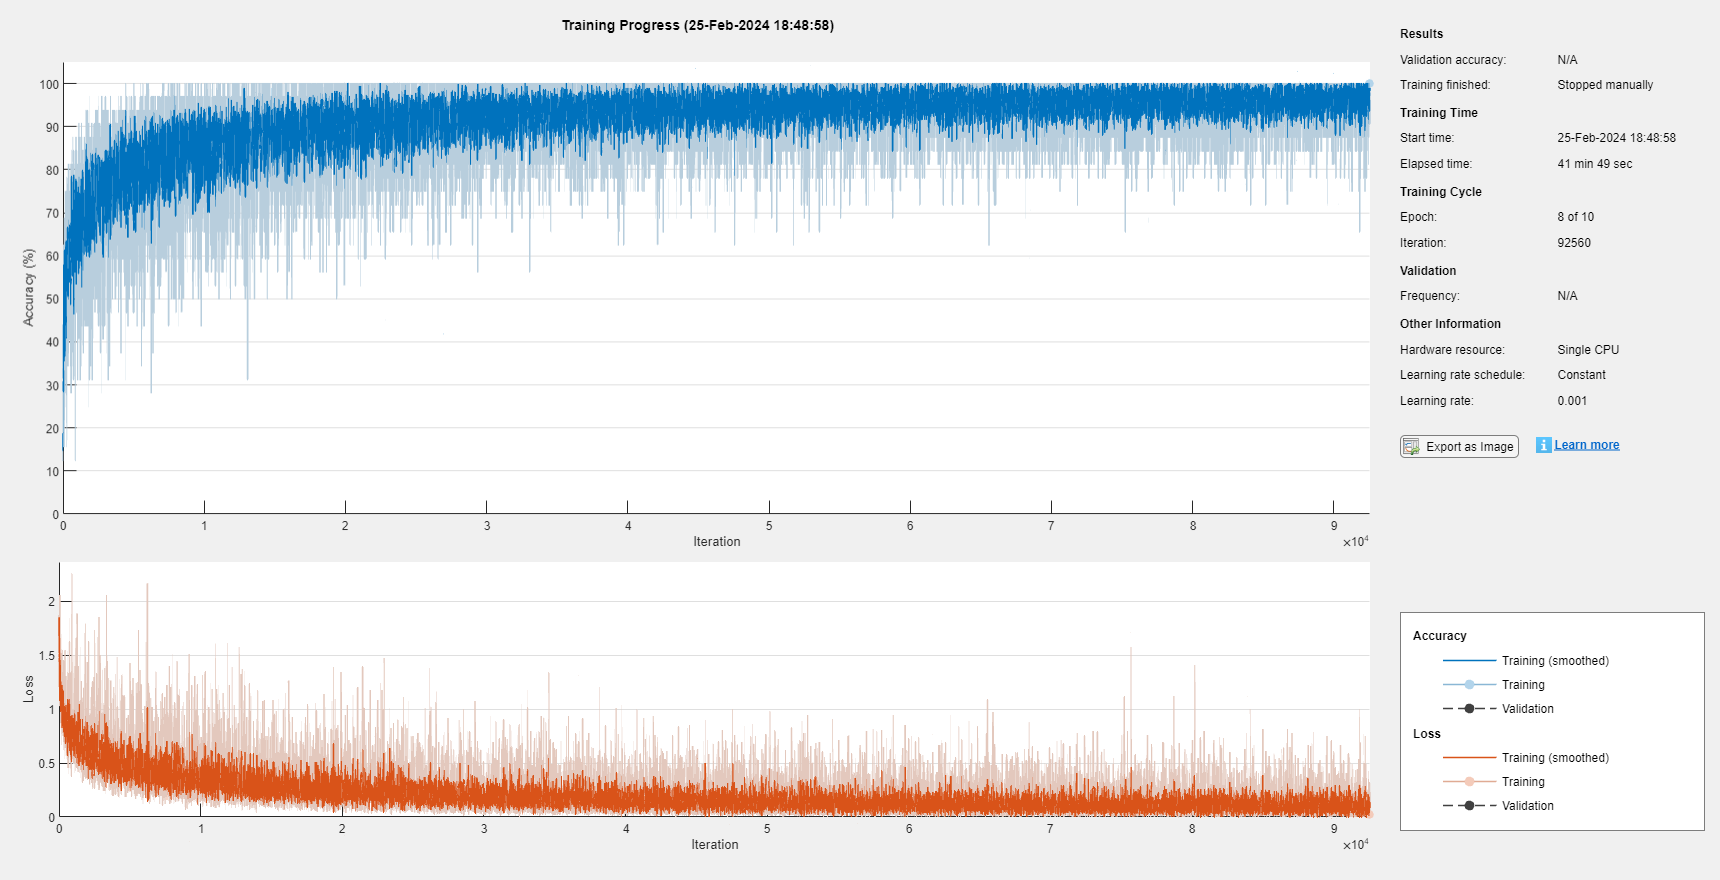

net =   SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers_TDN, options)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       25.00% |       1.7801 |          0.0010 |
|       1 |          50 |       00:00:02 |       37.50% |       1.5480 |          0.0010 |
|       1 |         100 |       00:00:03 |       25.00% |       1.7187 |          0.0010 |
|       1 |         150 |       00:00:04 |       15.62% |       1.8568 |          0.0010 |
|       1 |         200 |       00:00:05 |       43.75% |       1.2471 |          0.0010 |
|       1 |         250 |       00:00:06 |       37.50% |       1.4254 |          0.0010 |
|       1 |         300 |       00:00:07 |       43.75% |       1.

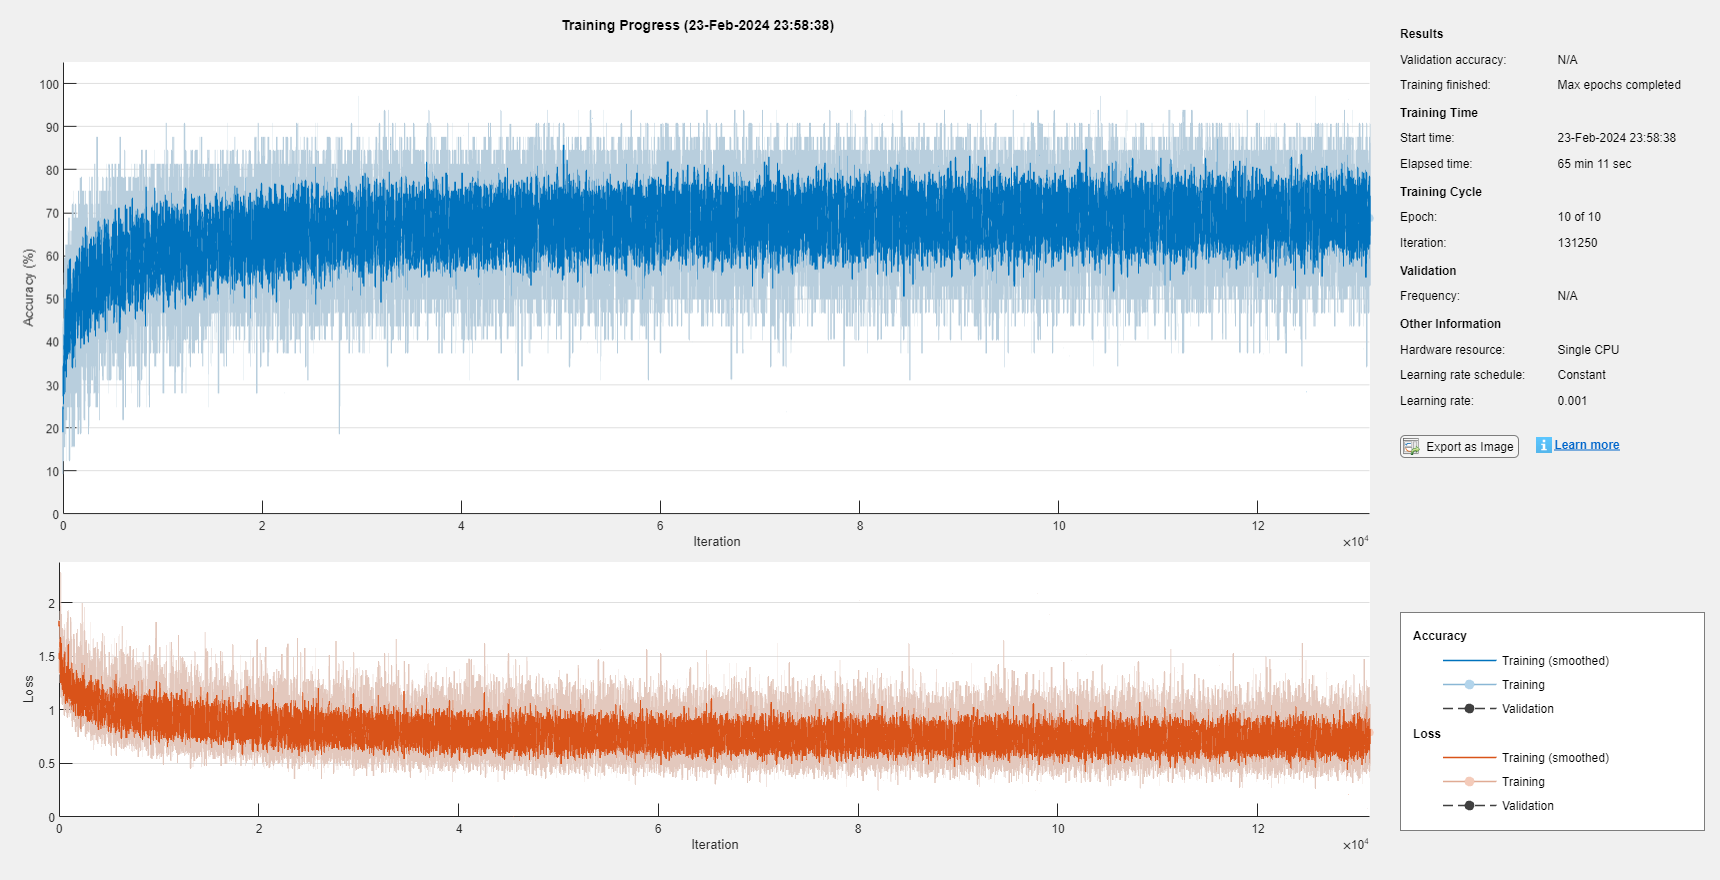

net =   SeriesNetwork with properties:

         Layers: [20×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers_TDN, options)

r_learned = predict(net, X_Test(:, end).').';

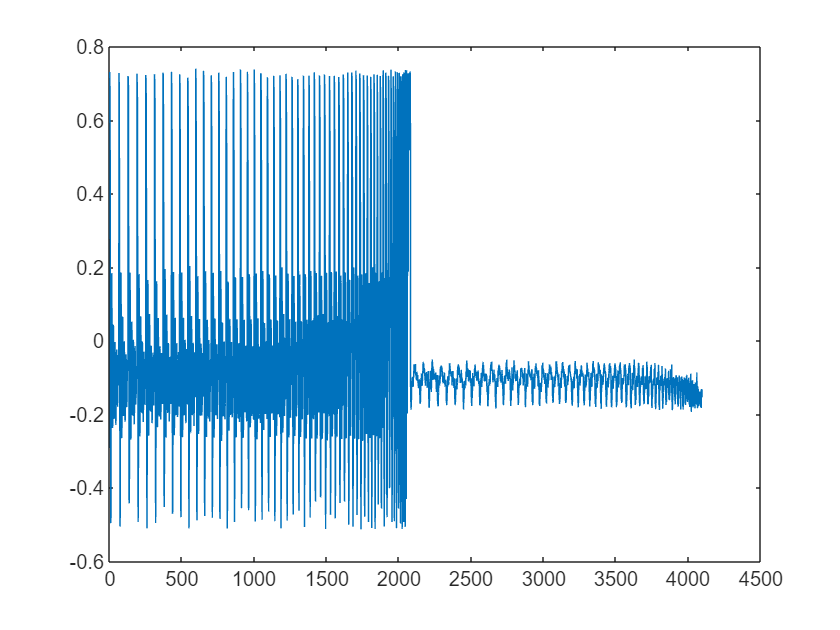

figure;
plot(r_learned);

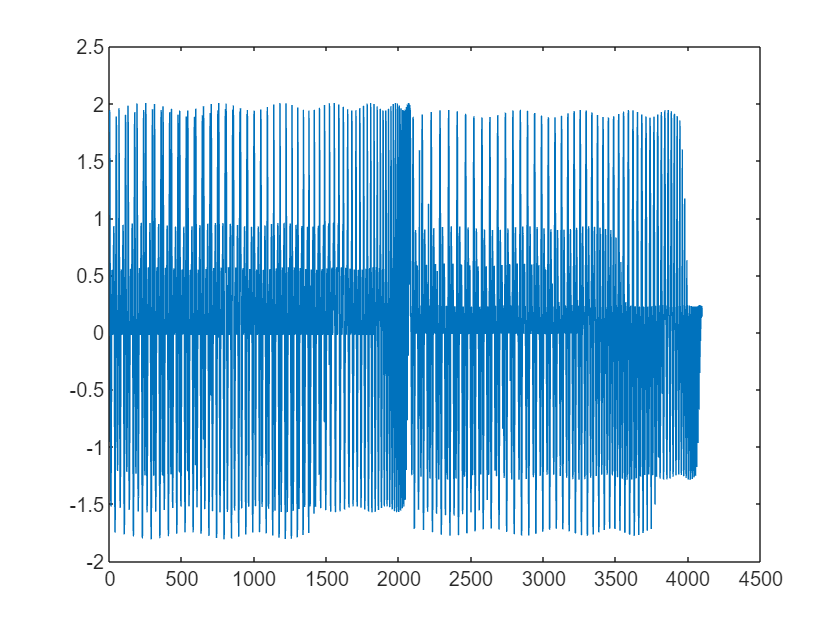

figure;
plot(Y_Test(:, end));

dsTrain.read()

ans = 1×2 cell array
    {4×4×2 double}    {[2]}


YPred = classify(net, X_Test);
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

accuracy = 0.6846

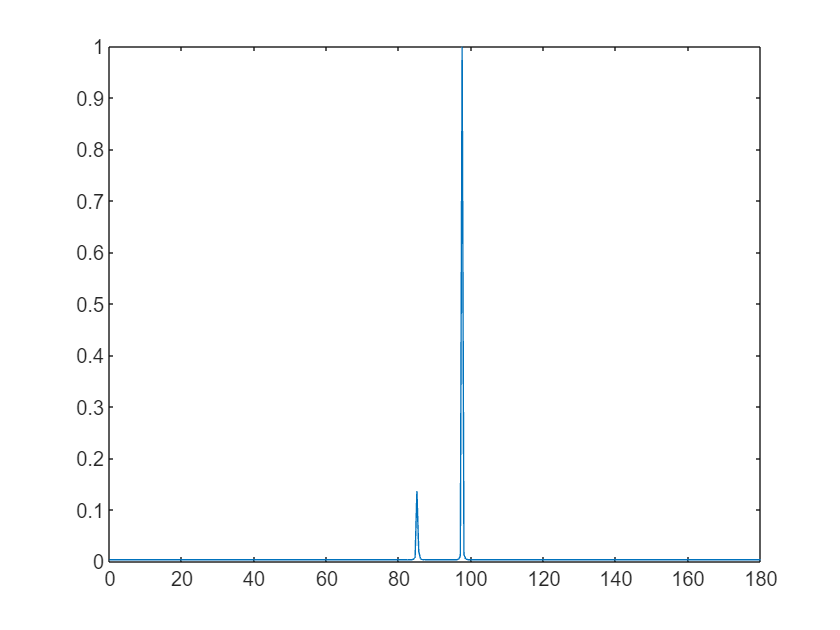

R = r2R(r);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

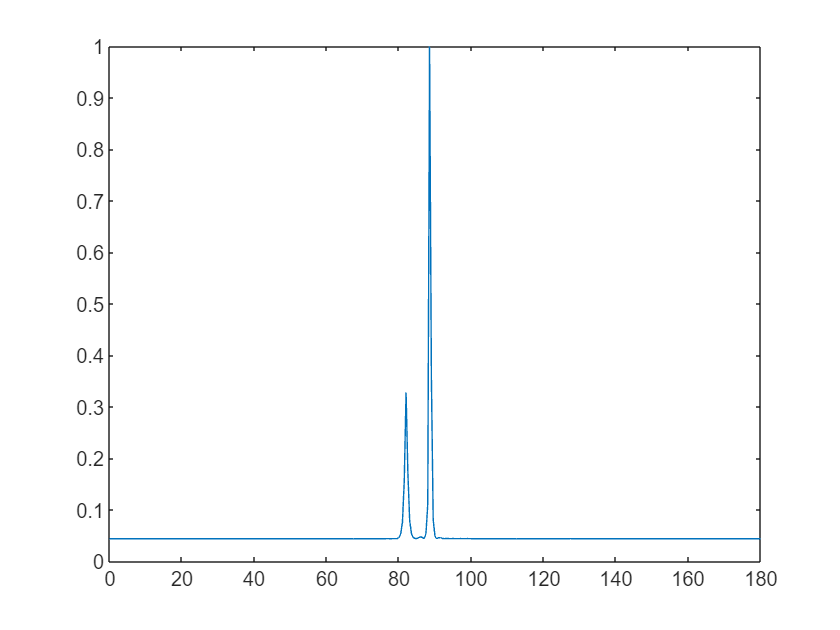

R = r2R(r_learned);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

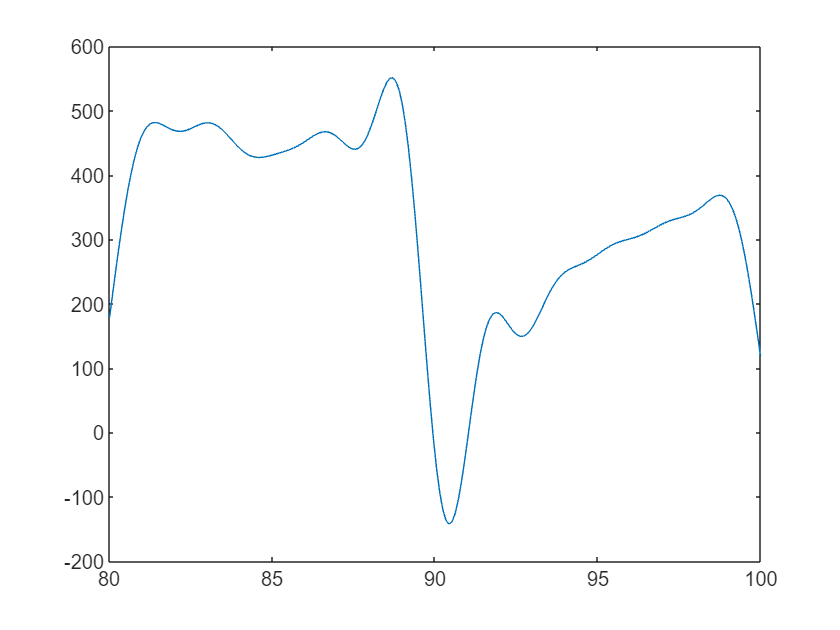

possible_angles = linspace(80, 100, 210);
P = length(possible_angles);
A_star = zeros(M2, P);
for p = 1:P
    A_star(:, p) = exp(1i * pi * (sensor_locations).' * cosd(possible_angles(p)));
end
A_tilda = DOA.khatri_rao(conj(A_star), A_star);

c = R(:);

ksa = A_tilda' * c;
figure;
plot(possible_angles, ksa);

function R = r2R(r)
vecSize = length(r);
% M = sqrt(vecSize + 0.25) + 0.5;
M = sqrt(vecSize);
split_idx = (M+1)*M/2; 
re_r = r(1:split_idx);
im_r = r(split_idx+1:end);
split_idx = 0;
for i = M:-1:1
    im_r = [im_r(1:split_idx); 0; im_r(split_idx+1:end)];
    split_idx = split_idx + i;
end
r2 = re_r + 1i * im_r;
R = zeros(M);
for i = 1:M
    split_idx = M-i+1;
    R(i, i:M) = r2(1:split_idx);
    r2 = r2(split_idx+1:end);
end
R = R + R';
for i = 1:M
    R(i, i) = R(i, i) / 2;
end
end